# Bandgap of Germanium

Increasing the temperature of the semiconductor causes electrons in the valence band to become thermally excited and jump to the conduction band. The large number of empty states in the conduction band, combined with the precense of holes in the valence band, allow the free flow of current.  The number of current carriers is proportional to the temperature by the following relationship (derived from statistical mechanics).

$n=f(T) e^{-\frac{E_{g}}{2 k_{B} T}}$ , where $f\left(T\right)$ varies with temperature as $T^{\frac{3}{2}}$.

The first part of our lab entailed measuring the band gap $E_g$ by 

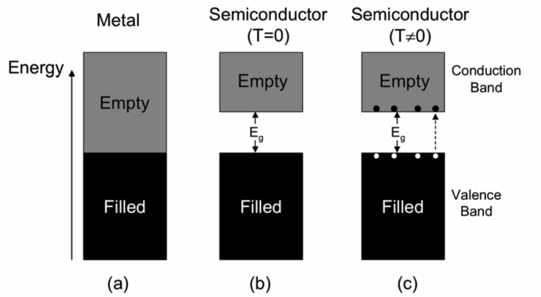

Controlling the conductivity of the semiconductor by means of doping can be done in two main ways. The first involves adding a small impurity that adds electrons to the conduction band (donor impurity), which results in an n-type semiconfuctor. The second involves adding an impurity that removes electrons from the valence band (acceptor impurity), which results in a p-type semiconductor.  

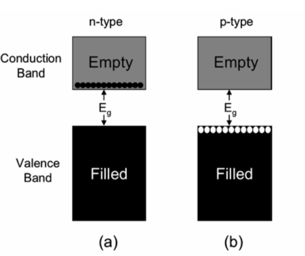

After connecting the leads and turning on the equipment, we set a voltage of 4.77V flowing through the 6234A power supply. Across the crystal we measured a current of 1.95 mA over a voltage drop of 1.396V.  The heater power supply was set to 4.2V, with an initial current of 0.1 A. 

Next, we slowly increased the current of the thermistor, which in turn increased the voltage. 

The thermistor was read with a voltmeter, using the following equation to read out the temperature.


$$T\left(K\right)=273+100*V$$


The thermistor voltage had a tendancy to fluctuate, even when the current was held constant. To account for this, we waited between two and three minutes after increasing the current before taking measurement of the corresponding voltage. Additionally, we set the temperature error to $\pm K$to account for the temperature drift. 

Analysis of the relationship between temperature and conductivity was performed by taking the log of both sides of the conductivity equation, producing the relationship.


$$\mathrm{ln}\left(\sigma \right)=-\frac{E_g }{2\mathrm{KT}}+{\mathrm{ln}\left(\sigma \right)}_0$$


Since the function of temperature vaires with $\frac{1}{2\mathrm{KT}}$, 


$$F\;=\;\mathrm{qE}=\frac{eV_H }{w}$$



$$F=\mathrm{evB}$$


data=dlmread('Bandgap.csv',',',1,0);
temp=data(:,2)*100+273;
l=.020;
l_err=.0001;
w=.010;
w_err=.0001;
t=.001;
t_err=.0001;
I=data(:,4);
I_err=.00001;
V=data(:,1);
V_err=.001;


$$\sigma=n e \mu \approx \sigma_{0} e^{-\frac{E_{g}}{2 k_{B} T}}$$


ratio $E_{g} / 2 k_{B} T$

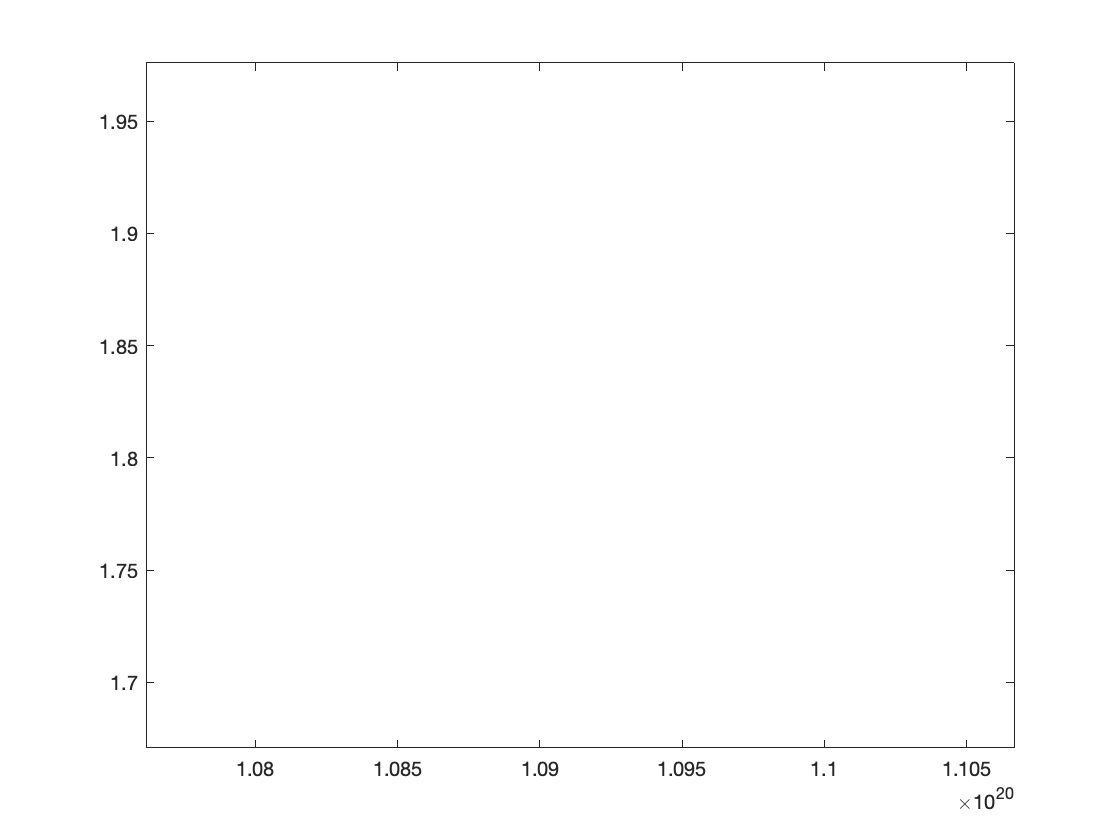

% Units? invere Joules or inverse eV?
k=1.381*10^(-23);
x=(2*k.*temp).^-1;
con=l*data(:,4)./(data(:,1)*w*t);
con_err=((l_err.*I./(V*w*t)).^2+(l*I_err./(V*w*t)).^2+(l.*I*V_err./(w*t.*V.^2)).^2 ...
    +(l.*I*w_err./(w^2*t.*V)).^2+(l.*I*t_err./(w.*V*t)).^2).^.5;
log_con_err=con_err./con;
plot(x,log(con),'s')

fit=myfit(x,log(con),log_con_err)

fit =    13.0823   -0.0000
    0.0255    0.0000


E_gap=-fit(1,2)./(1.6*10^-19)

E_gap = 0.6175

E_gap_err=fit(2,2)/(2.6*10^-19)

E_gap_err = 9.1176e-04

#### Doped Semi-Conductors and the Hall Effect

doped_data = dlmread('Doped.csv',',',1,0);
B = 10^(-4).*doped_data(:,1) % Tesla

B =    -0.1000
   -0.0800
   -0.0600
   -0.0400
   -0.0200
         0
    0.0200
    0.0400
    0.0600
    0.0800


B_err = 10^(-4).*doped_data(:,2);
V_H = 10^(-3).*doped_data(:,3); % Volts
V_H_err = 10^(-3).*doped_data(:,4);
t_crystal = 0.001; % meters
t_crystal_err = 0.0001; % meters
I = 18.6*10^(-3) % Amps

I = 0.0186

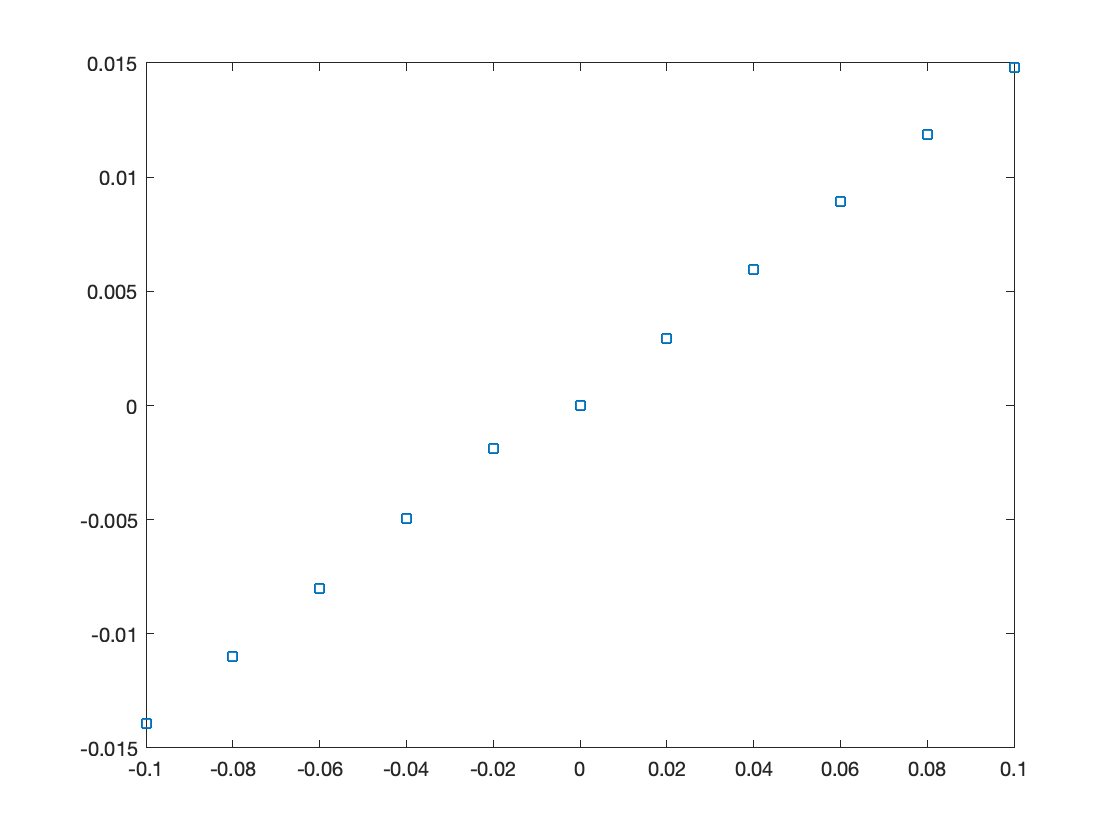

I_err = 0.1*10^(-3) ;
sz = size(B);
I = I.*ones(sz);
I_err = I_err.*ones(sz);
e = 1.6*10^(-19);
plot(B, V_H, 's')


$$n=\frac{I B}{e V_{H} t}$$


n = (I.*B)./(e.*V_H*t_crystal);
n = n([1:5, 7:11],:);
n_err = sqrt(((I_err.*B)./(e.*V_H.*t_crystal)).^2 + ((I.*B_err)./(e.*V_H.*t_crystal)).^2 + ...
    ((V_H_err.*I.*B)./(e.*V_H.^2.*t_crystal)).^2 + ((t_crystal_err.*I.*B)./(e.*V_H.*t_crystal.^2)).^2);
n_err = n_err([1:5, 7:11],:);
sum1 = sum(n./n_err.^2);
sum2 = sum(1./n_err.^2);
n_avg = sum1/sum2

n_avg = 8.3656e+20

n_avg_err = sqrt(1/sum2)

n_avg_err = 2.6729e+19

Copper: 8.5 * 10^28 e/m^3

function rval = myfit(x,y,ey)
    sx = sum(x ./ (ey .^ 2) );
    sy = sum(y ./ (ey .^ 2) );
    sxx = sum((x .* x) ./ (ey .^ 2) );
    sxy = sum((x .* y) ./ (ey .^ 2) );
    s = sum(1 ./ (ey .^ 2) );
    delta=sxx*s-sx*sx;
    a=(sxx*sy-sx*sxy)/delta;
    ea=sqrt(sxx/delta);
    b=(s*sxy-sx*sy)/delta;
    eb=sqrt(s/delta);
    rval=[ a, b ; ea, eb ];
end